# 3軸リンクアームロボットのモデリング

Author: Carlos Santacruz-Rosero, Ph.D.

Copyright 2016 The MathWorks, Inc.

## ロボットのパラメータ定義(リンクの長さ)

ThreeLinkRobot.l1 = 0.3;
ThreeLinkRobot.l2 = 0.2;
ThreeLinkRobot.l3 = 0.1

ThreeLinkRobot =     l1: 0.3000
    l2: 0.2000
    l3: 0.1000

## ロボットのツリーオブジェクトを作成

robot = robotics.RigidBodyTree()

robot =   RigidBodyTree のプロパティ:

    NumBodies: 0
       Bodies: {1×0 cell}
         Base: [1×1 robotics.RigidBody]
    BodyNames: {1×0 cell}
     BaseName: 'base'

## リンク1を作成して関節を接続

link1 = robotics.RigidBody('L1')

link1 =   RigidBody のプロパティ:

        Name: 'L1'
       Joint: [1×1 robotics.Joint]
    Children: {1×0 cell}


jnt1 = robotics.Joint('jnt1','revolute')

jnt1 =   Joint のプロパティ:

                      Type: 'revolute'
                      Name: 'jnt1'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]

jnt1.PositionLimits = deg2rad([-180, 180]);
setFixedTransform(jnt1, [eye(3),[0;0;0];[0 0 0 1]]);
jnt1.JointAxis = [0 1 0];

link1.Joint = jnt1;
addBody(robot, link1, 'base');

## リンク2を作成して関節を接続

link2 = robotics.RigidBody('L2');
jnt2 = robotics.Joint('jnt2','revolute');
jnt2.PositionLimits = deg2rad([0, 180]);
setFixedTransform(jnt2, [eye(3),[ThreeLinkRobot.l1;0;0];[0 0 0 1]]);
jnt2.JointAxis = [0 1 0];
link2.Joint = jnt2;
%
addBody(robot, link2, 'L1');

## リンク3を作成して関節を接続

link3 = robotics.RigidBody('L3');
jnt3 = robotics.Joint('jnt3','revolute');
jnt3.PositionLimits = deg2rad([-130, 130]);
setFixedTransform(jnt3, [eye(3),[ThreeLinkRobot.l2;0;0];[0 0 0 1]]);
jnt3.JointAxis = [0 1 0];
link3.Joint = jnt3;
addBody(robot, link3, 'L2');

## 関節とエンドエフェクターを作成

link4 = robotics.RigidBody('L4');
jnt4 = robotics.Joint('jnt4','fixed');
setFixedTransform(jnt4, [eye(3),[ThreeLinkRobot.l3;0;0];[0 0 0 1]]);
link4.Joint = jnt4;
addBody(robot, link4, 'L3');

## ツリー構造を可視化

showdetails(robot);

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1           L1         jnt1     revolute             base(0)   L2(2)  
   2           L2         jnt2     revolute               L1(1)   L3(3)  
   3           L3         jnt3     revolute               L2(2)   L4(4)  
   4           L4         jnt4        fixed               L3(3)   
--------------------


## ホームポジションの取得と表示

Qhome = robot.homeConfiguration

Qhome =   フィールドをもつ 1×3 の struct 配列:
    JointName
    JointPosition

qHome = [Qhome.JointPosition]

qHome =      0     0     0

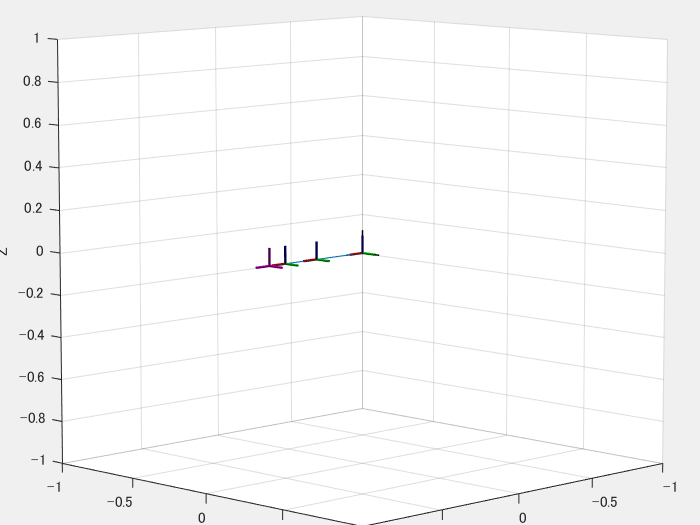

figure;
show(robot, Qhome);

## 順運動学計算とヤコビ行列計算

Q = robot.randomConfiguration();
q = [Q.JointPosition]

q =     3.0679    2.9201   -0.4106

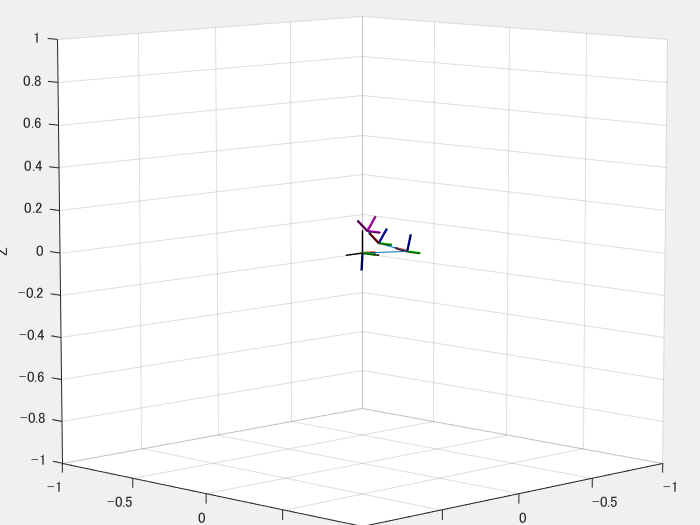

figure;
show(robot, Q);


T = getTransform(robot, Q, 'L4')

T =     0.7611         0   -0.6486   -0.0317
         0    1.0000         0         0
    0.6486         0    0.7611    0.1010
         0         0         0    1.0000


J = geometricJacobian(robot, Q, 'L4')

J =          0         0         0
    1.0000    1.0000    1.0000
         0         0         0
    0.1010    0.1230    0.0649
         0         0         0
    0.0317   -0.2675   -0.0761

## 逆運動学ソルバーの設定

ik = robotics.InverseKinematics('RigidBodyTree', robot);
weights = [1 1 1 1 1 1];
ikInitialGuess = robot.homeConfiguration;
q = [ pi/2 pi/2 pi/2];
ikInitialGuess = arrayfun(@(x,y) setfield(x, 'JointPosition', y), ikInitialGuess, q);

## 逆運動学計算

エンドエフェクターの姿勢を設定

Tee = eul2tform([0 pi/4 0]);
Tee(1:3,4) = [0 0 0.5*(ThreeLinkRobot.l1+ThreeLinkRobot.l2+ThreeLinkRobot.l3)] 

Tee =     0.7071         0    0.7071         0
         0    1.0000         0         0
   -0.7071         0    0.7071    0.3000
         0         0         0    1.0000

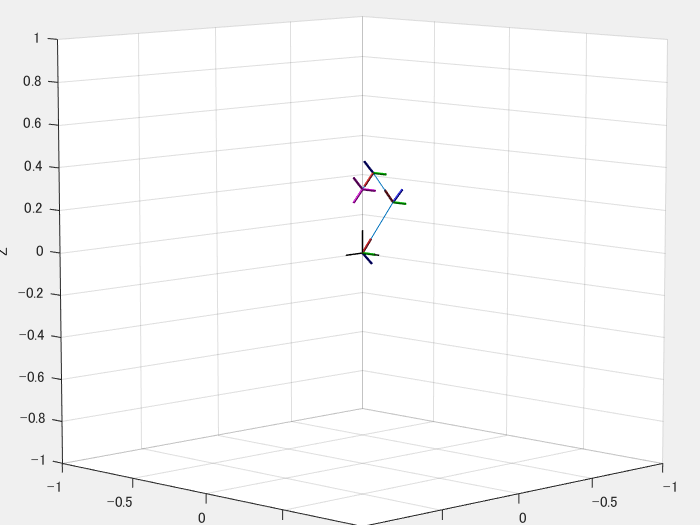


[QSol, SolInfo] = step(ik, 'L4', Tee, weights, ikInitialGuess);

figure;
show(robot, QSol);

qSol = [QSol.JointPosition]'

qSol =    -2.3145
    1.4671
    1.6328

% 計算結果の検証
Tik = getTransform(robot, QSol, 'L4')

Tik =     0.7071         0    0.7071    0.0000
         0    1.0000         0         0
   -0.7071         0    0.7071    0.3000
         0         0         0    1.0000